### **Define motor parameters**

R = 1; % Resistance
L = 0.5; % Inductance
Ke = 0.01; % Back EMF constant
Kt = 0.01; % Torque constant
J = 0.01; % Inertia
b = 0.1; % Friction coefficient

### **Create transfer function of the motor**

s = tf('s');
TF = Kt / ((J*s + b)*(L*s + R) + Kt*Ke);

### Simulation

t = 0:0.01:5;
reference_speed = 1;
[y, t] = step(reference_speed*TF, t);

### **Plot response**

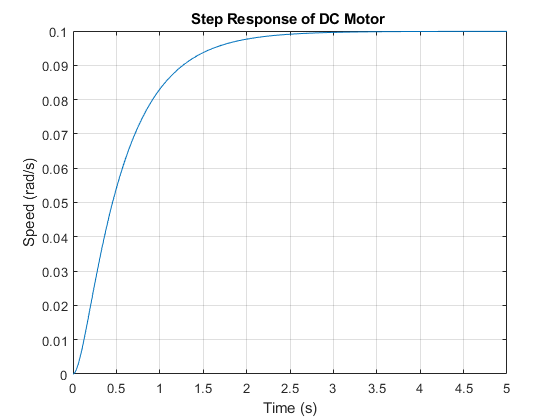

figure;
plot(t, y);
xlabel('Time (s)');
ylabel('Speed (rad/s)');
title('Step Response of DC Motor ');
grid on;